% Izhodišče krila je v (0,0)
%  _________________________________
% |             |  /                |
% |            C*D/alfa             |
% |_____A*D_____|/________B*D+D_____|
% |             |                   |
% |             C*D                 |
% |_____________|___________________|

%NACA podatki 
NACAn='9520'           

NACAn = '9520'

%Prvo število nam pove kako močna je ukrivljenost
%Drugo število nam pove kje se ukrivljenost začne (npr. 5 -> 0.5 celotne dolžine ...)
%Tretjo in četrto število poveta debelino krila
trailingedge="close";   %open/close Odprt ali zaprt zadnji rob

%Geometrija
lc = 0.05;
dx = 0.05;
A=2;      
B=5;        %0, če izbereš krilo
C=2;      
D=1;        %skaliranje krila, mora biti 1 če izbereš krog ali kvader
E=3; % not ven, vsaj 1
alfa=0;

N1=str2double(NACAn(1))

N1 = 9

N2=str2double(NACAn(2))

N2 = 5

N34=str2double(NACAn(3:4))

N34 = 20

st=500

st = 500

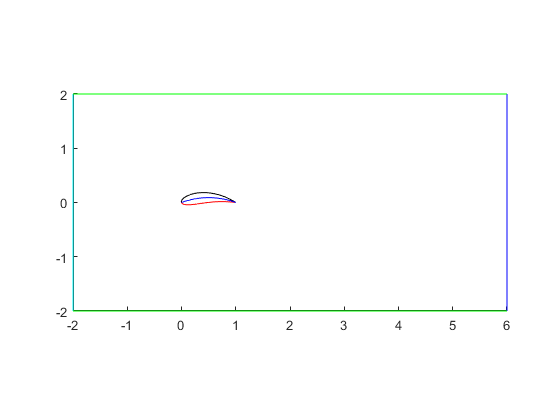

NACAkoor=NACAk(N1,N2,N34,trailingedge,A,B,C,D,st);

fileID = fopen(strcat('naca',NACAn,'.geo'),'w');
fprintf(fileID,"// NACA %s\n",NACAn);
fprintf(fileID,"lc = 0.05;\n");
fprintf(fileID,"lcb = 0.05;\n");


for i=1:length(NACAkoor)
   fprintf(fileID,"Point(%i) = {%f, %f, %f,  lc};\n",1000+i,-D/2+NACAkoor(i,1),-D/2,NACAkoor(i,2));
end
fprintf(fileID,"Spline(1000) = {1001:%i,1001};\n",1000+length(NACAkoor));
fprintf(fileID,"Line Loop (1) = {1000};\n");
fprintf(fileID,"Plane Surface (1) = {1};\n");
fprintf(fileID,"Extrude {0,%f,0} {\n",D);
fprintf(fileID,"Surface{1};\n");
fprintf(fileID,"Layers{1/lc};\n");
%fprintf(fileID,"Recombine;\n");
fprintf(fileID,"}\n");
fprintf(fileID,"Physical Surface('aerofoil') = {1,1006,1007};\n");


fprintf(fileID,"SetFactory('OpenCASCADE');\n");

fprintf(fileID,"Box(1) = {%i,%i,%i,%i,%i,%i};\n",-A*D-D/2,-E*D,-C*D,(A+B+1)*D,2*E*D,2*C*D);
fprintf(fileID,"Physical Surface('inlet') = {1008};\n");
fprintf(fileID,"Physical Surface('outlet') = {1009};\n");
fprintf(fileID,"Physical Surface('front') = {1010};\n");
fprintf(fileID,"Physical Surface('back') = {1011};\n");
fprintf(fileID,"Physical Surface('bottom') = {1012};\n");
fprintf(fileID,"Physical Surface('top') = {1013};\n");

fclose(fileID);



%NACA koordinate
hold off

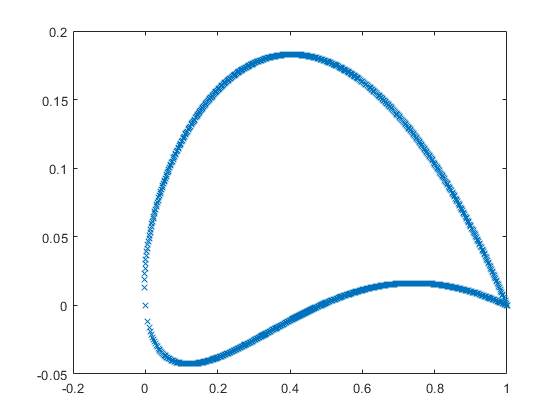

plot(NACAkoor(:,1),NACAkoor(:,2),'x')

function NACAkoordinate=NACAk(N1,N2,N34,trailingedge,A,B,C,D,st)
% Prepis
M=N1/100;
P=N2/10;
T=N34/100;


x=linspace(0,1,st)';

% Chamber & Gradient
yc=ones(st,1);
dycdx=ones(st,1);
theta=ones(st,1);
for i=1:1:st
    if (x(i)>=0 && x(i)<P)
        yc(i)=(M/P^2)*((2*P*x(i))-x(i)^2);
        dycdx(i)=((2*M)/(P^2))*(P-x(i));
    else
        yc(i)=(M/(1-P)^2)*(1-(2*P)+(2*P*x(i))-(x(i)^2));
        dycdx(i)=((2*M)/((1-P)^2))*(P-x(i));
    end
end

for i=1:1:st
    theta(i)=atan(dycdx(i));
end

% Thickness distribution

a0=0.2969;
a1=-0.1260;
a2=-0.3516;
a3=0.2843;

if trailingedge=="open"
a4=-0.1015;
elseif trailingedge=="close"
a4=-0.1036;
end

yt=ones(st,1);
for i=1:1:st
    term0=a0*sqrt(x(i));
    term1=a1*x(i);
    term2=a2*x(i)^2;
    term3=a3*x(i)^3;
    term4=a4*x(i)^4;
    
    yt(i)=5*T*(term0+term1+term2+term3+term4);
end

% Surface points

%Upper surface points

xu=ones(st,1);
yu=ones(st,1);
for i=1:1:st
    xu(i)=(x(i)-yt(i)*sin(theta(i)))*D;
    yu(i)=(yc(i)+yt(i)*cos(theta(i)))*D;
end

%lower surface points

xl=ones(st,1);
yl=ones(st,1);
for i=1:1:st
    xl(i)=(x(i)+yt(i)*sin(theta(i)))*D;
    yl(i)=(yc(i)-yt(i)*cos(theta(i)))*D;
end

% Plot
f1=figure(1);
hold on;
axis equal; 
plot(xu,yu,"k-")    %%zgornji del
plot(xl,yl,"r-")    %%spodnji del
plot(x*D,yc*D,"b-")     %chamfer line

plot([-A*D,-A*D],[-C*D,C*D],"c-")   %%front
plot([D+B*D,D+B*D],[-C*D,C*D],"b-")     %%back
plot([-A*D,D+B*D],[C*D,C*D],"g-")     %%top
plot([-A*D,D+B*D],[-C*D,-C*D],"g-")   %%bot
xlim([-A*D D+B*D])
ylim([-C*D C*D])


NACAkoordinate=zeros(2*st-2,2);
for i=1:st
    NACAkoordinate(i,1)=xu(i);
    NACAkoordinate(i,2)=yu(i);
end
for i=1:st-2
    NACAkoordinate(st+i,1)=xl(st-i);
    NACAkoordinate(st+i,2)=yl(st-i);
end



%Upoints=[xu,yu];
%Lpoints=[xl,yl];
%NACAkoordinate=[Upoints;Lpoints];


end